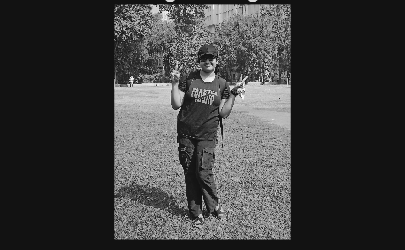

% Grey level slicing with background %
% Read the image
p = imread('DK.jpg');
p = rgb2gray(p);
z = double(p);
[row, col] = size(p);

for i = 1:1:row
    for j = 1:1:col
        % Check if pixel value is between 50 and 150
        if (z(i,j) > 50) && (z(i,j) < 150)
            z(i,j) = 255; % Set to white (highlight)
        else
            z(i,j) = p(i,j); % Keep original value (Retain background)
        end
    end
end

figure(1); %------- original image.
imshow(p);
title('Original Image');
exportgraphics(gcf, 'GL2.png', 'Resolution', 300)




figure(2); %------- grey level slicing with background
imshow(uint8(z));
title('Gray Level Slicing with Background');

exportgraphics(gcf, 'GL1.png', 'Resolution', 300)